# 数据导入

clc;
clear all;

## 单面点云

%%%%%%%%%%%%%%%%%%使用单面点云拟合时要将8-9行代码取消注释同时注释掉双面点云拟合段
filepath = "E:\02技术资料\65\23260190240-1-1.txt";%单面点云路径
Data = importdata(filepath);
ImpData = Data.data;
% 平移对准
x0 = ImpData(:,1); y0 = ImpData(:,2); z0 = ImpData(:,3);
[y0,z0] = Re(y0,z0);
[x0,z0] = Re(x0,z0);
ImpData = [x0,y0,z0];
% n0 = length(x0);
% a0 = [x0,y0,z0,ones(n0,1)];
% u0 = [-(max(x0)+min(x0))/2,-min(abs(y0)),-mean(z0)]; 
% Tr0 = [1,0,0,u0(1);0,1,0,u0(2);0,0,1,u0(3);0,0,0,1];
% A0 = a0*Tr0';
%%%%%%%%%%%%%%%%%%%
% theta = -180;
% M = [A0(:,1),A0(:,2)]*[cosd(theta),-sind(theta);sind(theta),cosd(theta)]';
% ImpData = [M(:,1),M(:,2),A0(:,3)];
%%%%%%%%%%%%%%%%%
% ImpData = [A0(:,1),A0(:,2),A0(:,3)];

## 双面点云

%%%%%%%%%%%%%%%%%使用双面点云拟合时将单面代码行注释掉
%%%%%%%%%%%%%%%%%不要注释第7行代码避免最后保存代码报错
%点云对应路径
% data1 = importdata("E:\SF\547-20230134\A.txt");
% data2 = importdata("E:\SF\547-20230134\B.txt");
% %点云配准
% x0 = data1.data(:,1); y0 = data1.data(:,2); z0 = data1.data(:,3);
% % [y0,z0] = Re(y0,z0);
% x1 = data2.data(:,1); y1 = data2.data(:,2); z1 = data2.data(:,3);
% % [y1,z1] = Re(y1,z1);
% n0 = length(x0);
% a0 = [x0,y0,z0,ones(n0,1)];
% u0 = [0,min(abs(y0)),-mean(z0)]; 
% Tr0 = [1,0,0,0;0,1,0,u0(2);0,0,1,u0(3);0,0,0,1];
% A0 = a0*Tr0'; x0 = A0(:,1); y0 = A0(:,2); z0 = A0(:,3);
% n1 = length(x1);
% a1 = [x1,y1,z1,ones(n1,1)];
% u1 = [0,min(abs(y1)),-mean(z1)]; 
% Tr1 = [1,0,0,0;0,1,0,u1(2);0,0,1,u1(3);0,0,0,1];
% A1 = a1*Tr1'; x1 = A1(:,1); y1 = A1(:,2); z1 = A1(:,3);
% %%%%%%%%%%%%%%%旋转180配准情况
% % theta = -180;
% % A = [x1,y1]*[cosd(theta),-sind(theta);sind(theta),cosd(theta)]';
% % x1 = A(:,1); y1 = A(:,2);
% %%%%%%%%%%%%%%%
% x = -x1; y = y1; z = z1;
% data1.data = [x0,y0,z0];
% data2.data = [x,y,z];
% ImpData = [data1.data;data2.data];

## 前处理

d = 1;%网格大小
[xq, yq, zq] = PreprocessDate(ImpData,d);
% [yq,zq] = Re(yq,zq);
% [xq,zq] = Re(xq,zq);

## 单侧拟合

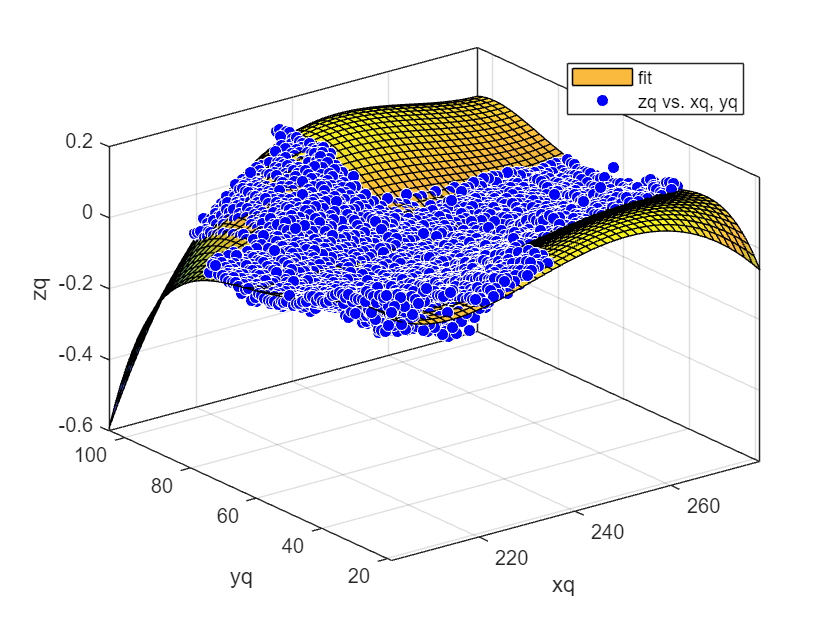

ii = xq > 0;
n = 4;%拟合方程次数
[f1  gof1] = createFit(xq(ii), yq(ii), zq(ii), n);

P1 = coeffvalues(f1);%多项式系数向量
s1 = dispf(P1,n,n);
disp(s1)

109.0632 + -0.49556*Y + -0.004515*Y*Y + 2.1342e-06*Y*Y*Y + -7.5476e-08*Y*Y*Y*Y + -1.6594*X + 0.0081908*X*Y + 3.6705e-05*X*Y*Y + 6.5391e-08*X*Y*Y*Y + 0.0091347*X*X + -4.2354e-05*X*X*Y + -9.8087e-08*X*X*Y*Y + -2.1279e-05*X*X*X + 7.2717e-08*X*X*X*Y + 1.7187e-08*X*X*X*X 


disp(gof1)

           sse: 0.8547
       rsquare: 0.8766
           dfe: 3973
    adjrsquare: 0.8762
          rmse: 0.0147




[f2  gof2] = createFit(xq(~ii), yq(~ii), zq(~ii), n);

错误使用 fit>iFit
数据不足。
您需要至少 15 个数据点才能拟合此模型。

出错 fit (第 116 行)
[fitobj, goodness, output, convmsg] = iFit( xdatain, ydatain, fittypeobj, ...

出错 createFit (第 35 行)
[fitresult, gof] = fit( [xData, yData], zData, ft,'Normalize', 'off');

P2 = coeffvalues(f2);%多项式系数向量
s2 = dispf(P2,n,n);
disp(s2)
disp(gof2)


## 双侧拟合

n = 4;%拟合方程次数
[f3  gof3] = createFit(xq, yq, zq, n);
P3 = coeffvalues(f3);%多项式系数向量
s3 = dispf(P3,n,n);
disp(s3)
disp(gof3)